# TAIM_1 

## Load Data

load evData.mat

## Draw Data

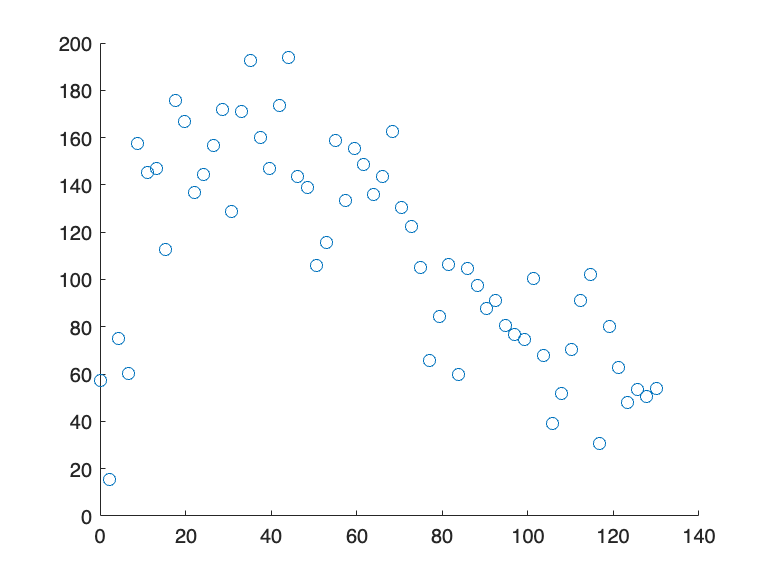

scatter(speed,range)

## First Basic Fitting

We can do a first basic fitting using the plot tools. **Tools > Basic Fitting**

This displays a window to select the type of fitting we want:

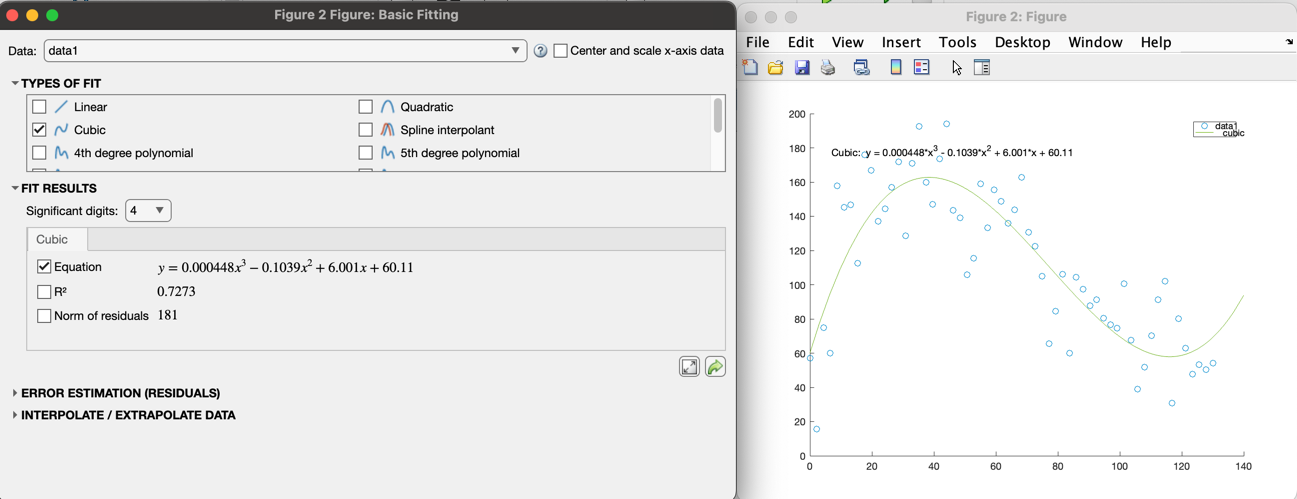

## Better Fitting using Apps

Go to **Apps > Curve Fitter**

Then click **Select Data **and enter the following ranges:

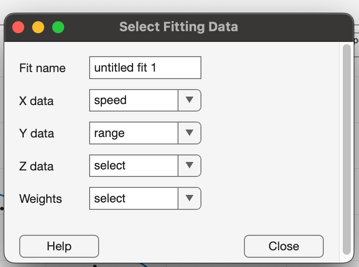

We then create any fittings we want.

Finally, we can **export** the fittings to our workspace.

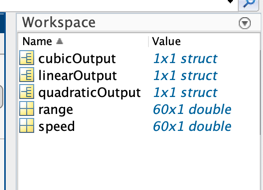

Use the following command to save the fittings in an output: **'save fitOutput.mat cubicOutput quadraticOutput linearOutput' **and they will be created here:

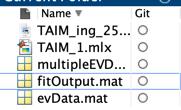

If we used **'save xxx.mat' **we save all of the variables instead of the fittings only.

## Process Results

load fitOutput.mat;

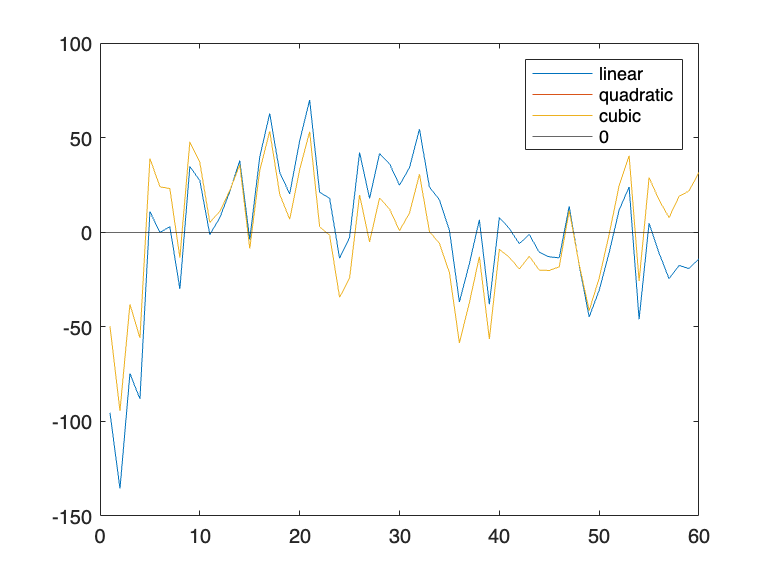

figure('Name', 'Figure 1');
res = linearOutput.residuals;
plot(res)
hold on
resq = quadraticOutput.residuals;
resc = cubicOutput.residuals;
plot(resq)
plot(resc)
yline(0)
hold off
legend(["linear","quadratic","cubic","0"])

## Analysis

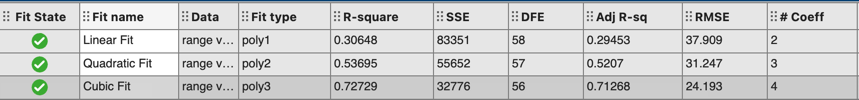

R-Square = 1 when perfect fit

R-Square = 0 when fit does not align at all

SSE = Sum of errors, lower is better

Seeing the results, we can conclude that we should introduce more coefficients to get better results.

load goodnessOutput.mat

Create an array:

goodness = [goodness1 goodness2 goodness3 goodness4 goodness5];

Convert to table:

goodness = struct2table(goodness);

Plot:

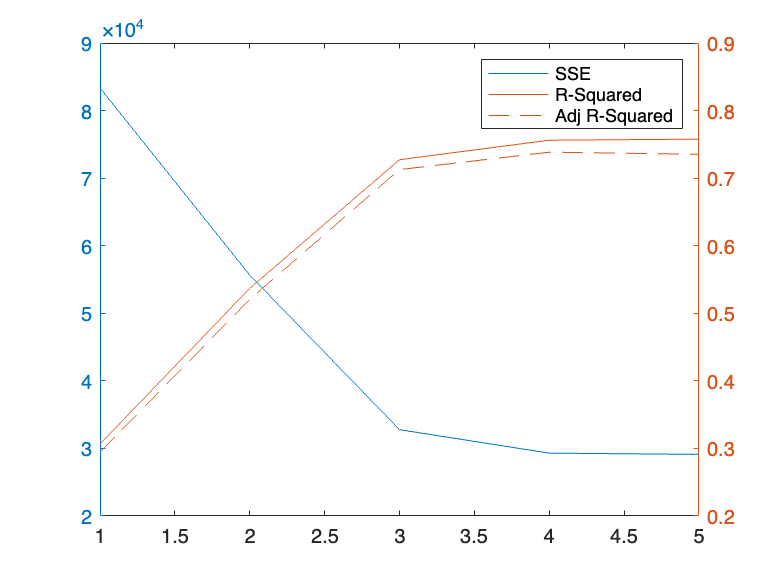

figure('Name', 'Figure 2');
yyaxis left
plot(goodness,"sse")
yyaxis right
plot(goodness,"rsquare")
hold on
yyaxis right
plot(goodness,"adjrsquare")
legend(["SSE","R-Squared","Adj R-Squared"])
hold off

## Call a Custom EV Model

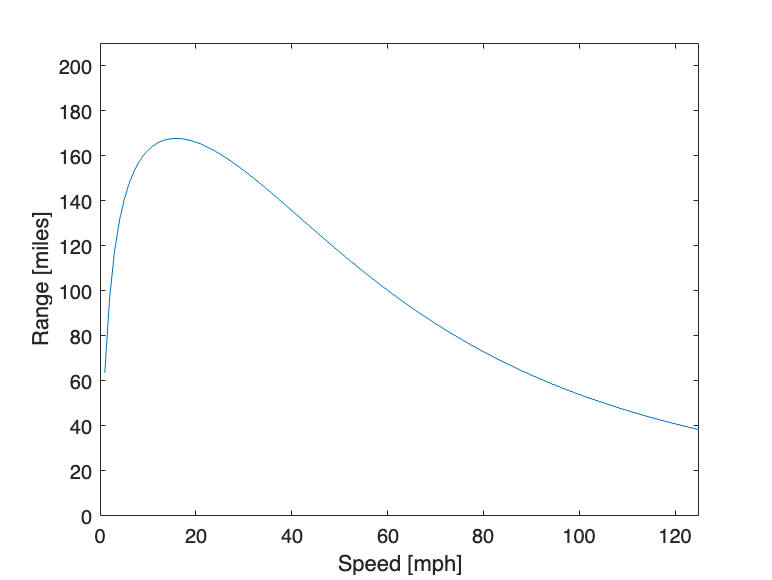

close all;
battEfficiency = 1;
auxPower = 60;
[speed, range] = evModel(battEfficiency,auxPower);
figure('Name', 'Figure 3');
plot(speed,range);
axis([0 125 0 210])
ylabel("Range [miles]")
xlabel("Speed [mph]")

## Find the Most Efficient Driving Speed

Method 1: use the fit to calculate optimal speed

load fittedmodel.mat
ValsTest = feval(fittedmodel, speed);
[maxVal,idx] = max(ValsTest);
speedBest = speed(idx)

speedBest = 30

Method 2: calculate the slope=0 and find the corresponding speed

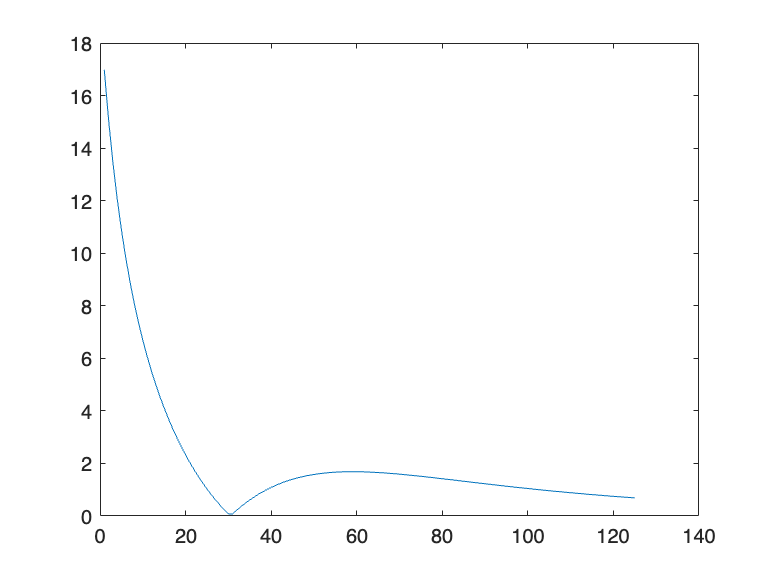

d = differentiate(fittedmodel,speed);
figure('Name', 'Figure 4');
plot(speed,abs(d))

[minVal, idx] = min(abs(d));
speedBest2 = speed(idx)

speedBest2 = 30

rMax = feval(fittedmodel, speedBest2)

rMax = 168.8559

## Work with Generated Code

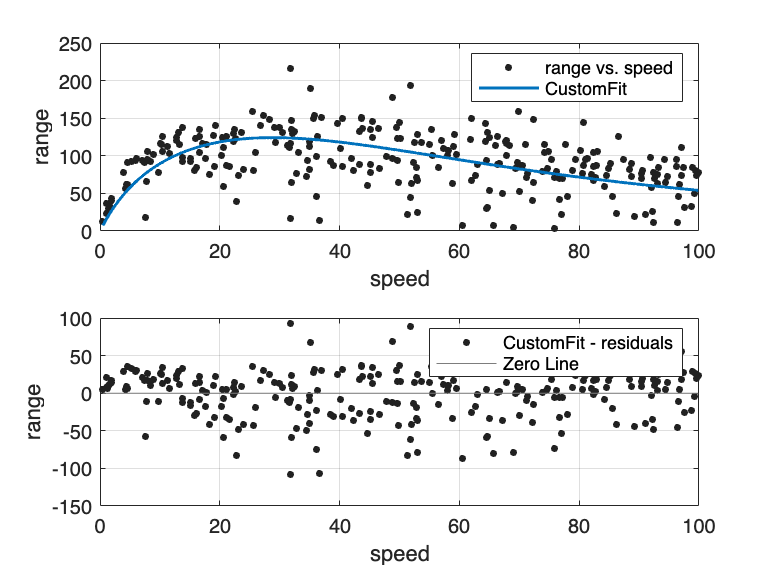

load multipleEVData.mat
carNumber = 42;
[fittedmodel,goodness] = createFit(speedData{carNumber},rangeData{carNumber});

coeff = coeffvalues(fittedmodel);

## Apply Generated Code to Multiple Data Sets

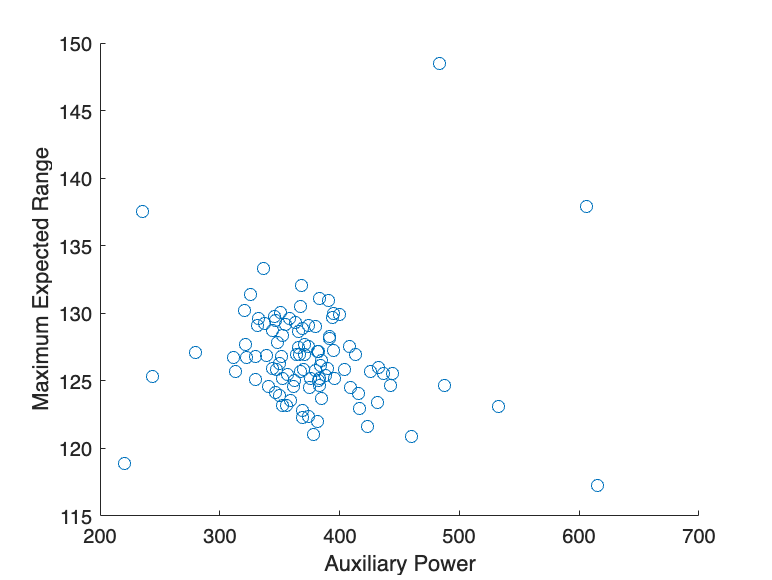

nCars = 100;
coeffs = zeros(nCars,2);
speedBest = zeros(nCars,1);
maxRange = zeros(nCars,1);

for carNumber = 1:nCars
    [fittedmodel, ~ , speedBest(carNumber), maxRange(carNumber)] = createFit2(speedData{carNumber},rangeData{carNumber});
    coeffs(carNumber,:) = coeffvalues(fittedmodel);
end

figure("Name", "Figure 5")
scatter(coeffs(:,1),maxRange)
xlabel("Auxiliary Power")
ylabel("Maximum Expected Range")

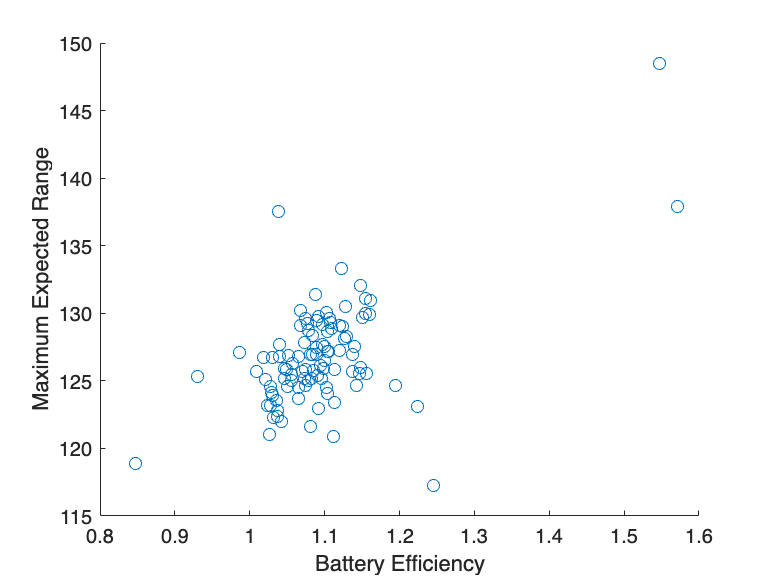

figure
scatter(coeffs(:,2),maxRange)
xlabel("Battery Efficiency")
ylabel("Maximum Expected Range")

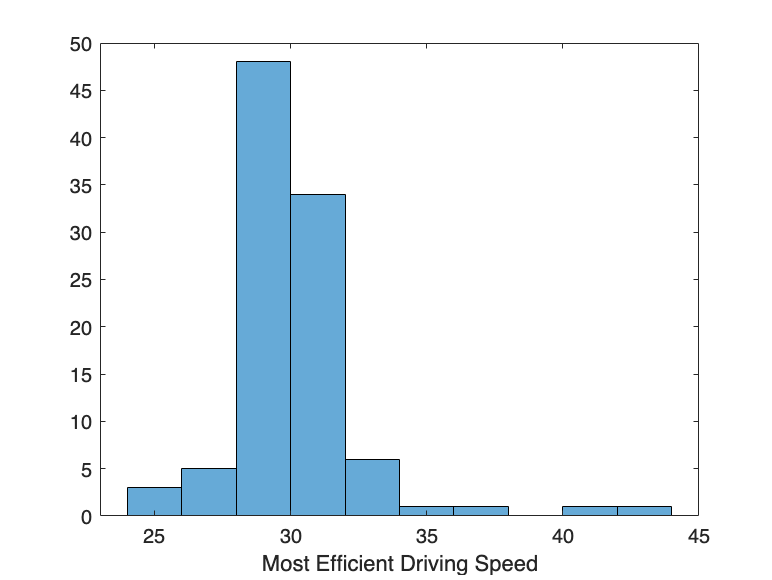

figure
histogram(speedBest)
xlabel("Most Efficient Driving Speed")

## Extra

nCars = 100;
coeffs = zeros(nCars,2);
speedBest = zeros(nCars,1);
maxRange = zeros(nCars,1);

for carNumber = 1:nCars
    [fittedmodel, ~ , speedBest(carNumber), maxRange(carNumber)] = createFit2(speedData{carNumber},rangeData{carNumber});
    coeffs(carNumber,:) = coeffvalues(fittedmodel);
    if fittedmodel.battEfficiency < .85
        carNumber
        fittedmodel.auxPower
    end
end

carNumber = 32

ans = 220.2463

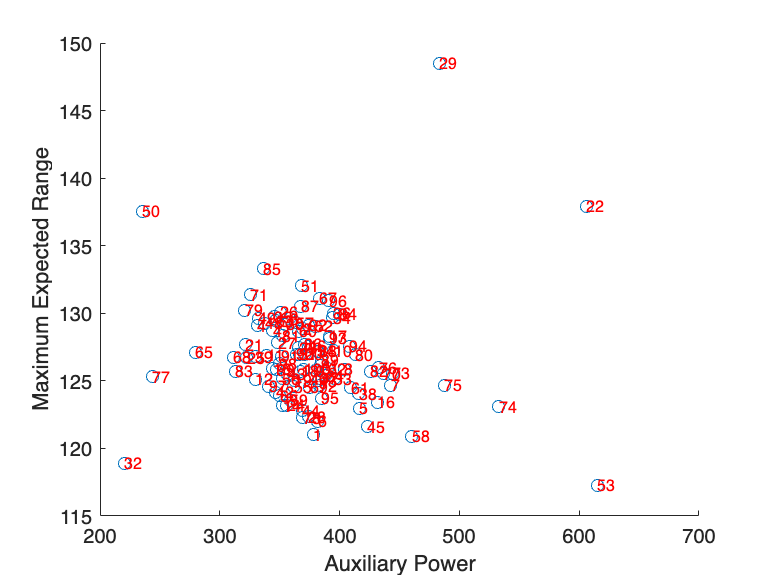



scatter(coeffs(:,1), maxRange)
xlabel("Auxiliary Power")
ylabel("Maximum Expected Range")
hold on
for carNumber = 1:nCars
    text(coeffs(carNumber,1), maxRange(carNumber), sprintf('%d', carNumber), 'FontSize', 8, 'Color', 'r')
end
hold off

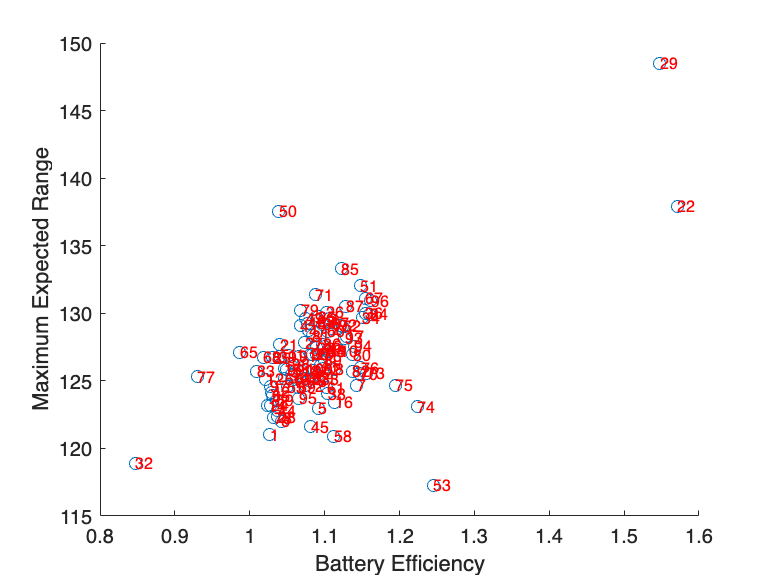


figure
scatter(coeffs(:,2), maxRange)
xlabel("Battery Efficiency")
ylabel("Maximum Expected Range")
hold on
for carNumber = 1:nCars
    text(coeffs(carNumber,2), maxRange(carNumber), sprintf('%d',carNumber), 'FontSize', 8, 'Color', 'r')
end
hold off